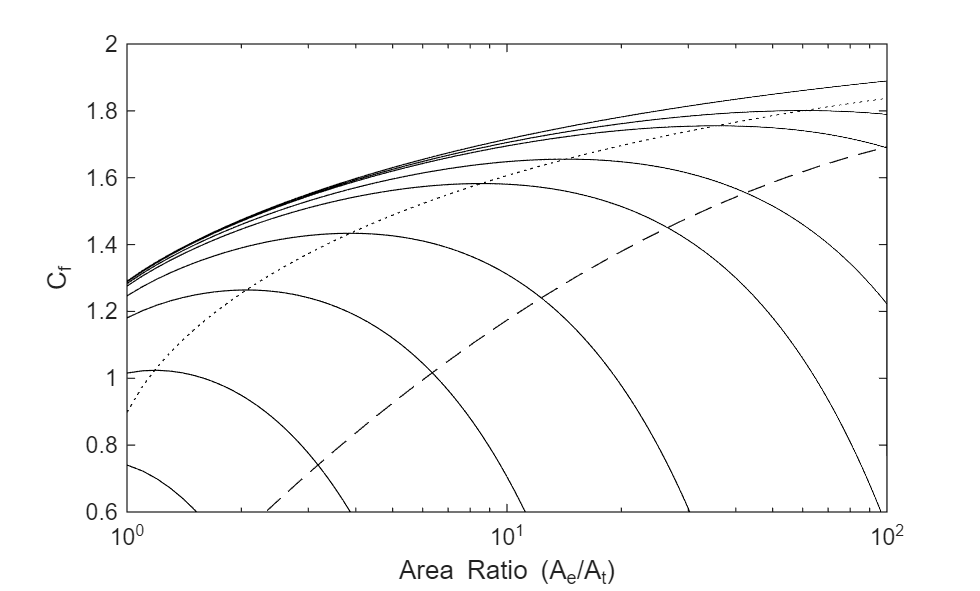

clear; close all; clf; clc; 
AR = 0:0.1:100;
curve1 = zeros(length(AR),1);
curve2 = zeros(length(AR),1);
curve3 = zeros(length(AR),1);
curve4 = zeros(length(AR),1);
curve5 = zeros(length(AR),1);
curve6 = zeros(length(AR),1);
curve7 = zeros(length(AR),1);
curve8 = zeros(length(AR),1);
curve9 = zeros(length(AR),1);
curve10 = zeros(length(AR),1);
ratioOfTheSpecificHeats = 1.25;

for index = 1:1000
    ratio = index/10;
    curve1(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,2);
    curve2(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,4);
    curve3(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,10);
    curve4(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,25);
    curve5(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,75);
    curve6(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,150);
    curve7(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,500);
    curve8(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,1000);
    curve9(index) = thrust_coefficient(ratioOfTheSpecificHeats,ratio,100000000);
    curve10(index) = thrust_coefficient_special(ratioOfTheSpecificHeats,ratio);
end




cfmin = @(ar) -0.0445*log(ar).^2 + 0.5324.*log(ar) + 0.1843;
figure(1);
semilogx(AR,curve1,AR,curve2,AR,curve3,AR,curve4,AR,curve5,AR,curve6,AR,curve7,AR,curve8,AR,curve9,'Color','k')
hold on;
semilogx(AR,curve10,':','Color','k')
fplot(cfmin,'--','Color','k');
ylim([0.6 2])
xlim([1 100])
xlabel('Area Ratio (A_e/A_t)')
ylabel('C_f')
hold off;

cf_proj4a = thrust_coefficient(1.2,57.43,100000000000000);
fprintf('the thrust coefficient at gamma = 1.25, epsilon = 10, P_c/P_a = infinity is C_f = %f',cf_proj4a)

the thrust coefficient at gamma = 1.25, epsilon = 10, P_c/P_a = infinity is C_f = 1.913058

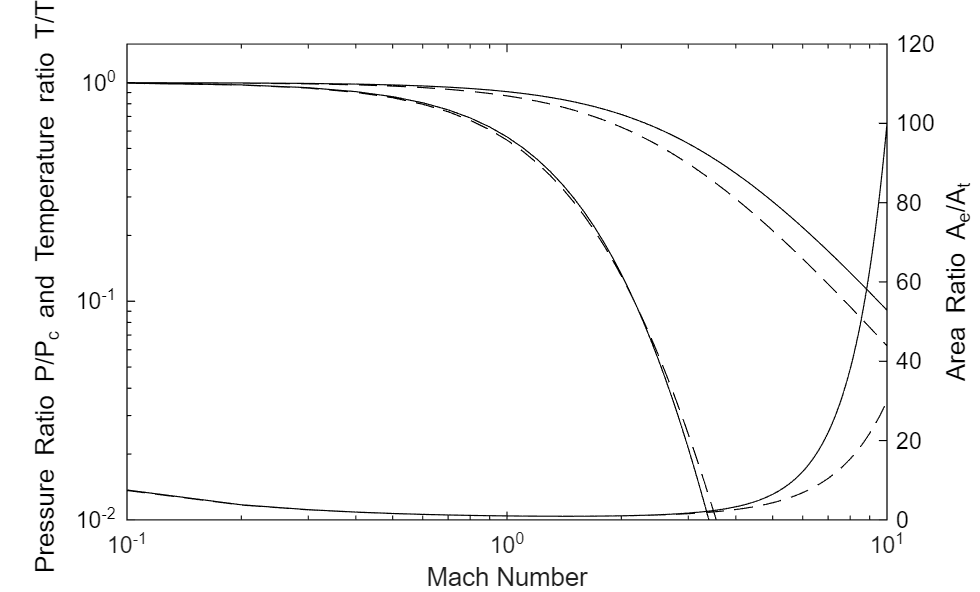


mach = 1:100;
mach = mach./10;

for jndex = 1:100
    machl = jndex/10;
    [pr1(jndex),tr1(jndex),ar1(jndex)] = isentropicRatios(1.2,machl);
    [pr2(jndex),tr2(jndex),ar2(jndex)] = isentropicRatios(1.3,machl);
end
figure(2);
colororder({'k','k'})
yyaxis left;
loglog(mach,pr1,'k-',mach,tr1,'k-')
hold on;
loglog(mach,pr2,'k--',mach,tr2,'k--')
hold on;
ylim([0.01 1.5])
ylabel('Pressure Ratio P/P_c and Temperature ratio T/T_c')
yyaxis right;

loglog(mach,ar1,'k-',mach,ar2,'k--')
xlim([0 10])
ylabel('Area Ratio A_e/A_t')
xlabel('Mach Number')







function [PPc,TTc,AreaRatio] = isentropicRatios(gamma,MachNumber)
% finds the isentropic relasionships pressure, temperature, and area

    PPc = (1 + (gamma - 1)/2 * MachNumber * MachNumber) ^ (-gamma/(gamma-1));

    TTc = (1 + (gamma - 1)/2 * MachNumber * MachNumber)^(-1);

    AreaRatio = MachNumber^-1 * (( 2 + (gamma-1) * MachNumber * MachNumber)/(gamma+1))^(gamma/(2*gamma-2));

end


function [cf] = thrust_coefficient(gamma,areaRatio,pcpa)
% Calculate the thrust coefficient using the given parameters
    [~,mach] = machNumbers(areaRatio,gamma);

    pcpe = (1+ (gamma-1)/2*mach^2)^(gamma/(gamma-1));

    pepc = pcpe^(-1);

    papc = pcpa^(-1);

    cf = (2*gamma^2/(gamma-1)*(2/(gamma+1))^((gamma+1)/(gamma-1))*(1-pepc^((gamma-1)/gamma)))^0.5 + (pepc - papc)*areaRatio;
end

function [cf] = thrust_coefficient_special(gamma,areaRatio)
% Calculate the thrust coefficient using the given parameters
    [~,mach] = machNumbers(areaRatio,gamma);

    pcpe = (1+ (gamma-1)/2*mach^2)^(gamma/(gamma-1));

    pepc = pcpe^(-1);

    papc = pepc;

    cf = (2*gamma^2/(gamma-1)*(2/(gamma+1))^((gamma+1)/(gamma-1))*(1-pepc^((gamma-1)/gamma)))^0.5 + (pepc - papc)*areaRatio;
end


function [M_sub, M_super] = machNumbers(areaRatio, gamma)
% machNumbers - Computes the subsonic and supersonic Mach numbers
% corresponding to a given area ratio A/A*

    f = @(M) (1./M) .* ( (2/(gamma+1)) .* (1 + (gamma-1)/2 .* M.^2) ) ...
        .^((gamma+1)/(2*(gamma-1))) - areaRatio;

    try
        M_sub = fzero(f, [1e-6, 0.999]); 
    catch
        M_sub = NaN; 
    end

    try
        M_super = fzero(f, [1.0001, 50]); 
    catch
        M_super = NaN;
    end
end